# SCARA Manipulator PSDM Example

This example shows how PSDM can be used to derive the regressor for of the dynamics of motion of a s SCARA manipulator

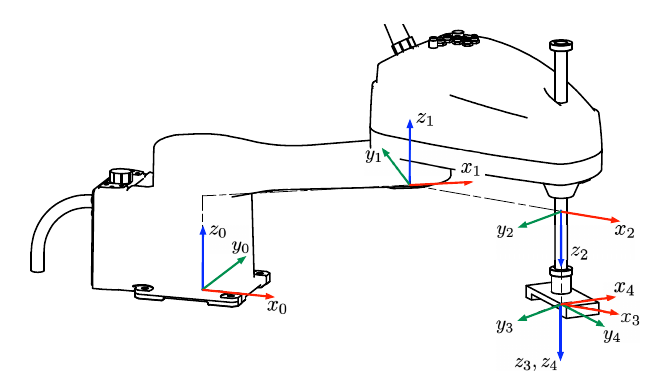

## Derivation

First, we define the DH table of the maniuplator. For the input to this toolbox, DH table must be defined as a $n\times 6%$ double matrix:


$$\text{DH} = \left[\matrix{
a_1 & \alpha_1 & d_1 & \theta_1 & t_1 & s_1 \cr
\vdots &\vdots &\vdots &\vdots &\vdots &\vdots \cr
a_n & \alpha_n & d_n & \theta_n & t_n & s_n \cr
 }\right]$$


where $a_i, \alpha_i, d_i$ and $\theta_i$ are the normal DH parameters, $t_i$ indicates the joint type (0 for revolute, 1 for prismatic) and $s_i$ is either a 1 or a -1, and indicates the direction of the joint. Internally, they are combined to make the DH table:


$$\left|
\matrix{
\text{Link Length } a_i & \text{Link twist } \alpha_i & \text{Link offset} d_i & \text{Joint angle } \theta_i \cr
a_i & \alpha_i & d_i + t_i s_i q_i & \theta_i + (1-t_i)s_i q_i
}
\right|$$


For the current robot, with link lengths 0.25, 0.3 and 0.15 m, we have the DH table:

DH = [0.25,     0,      0.4,    0,    0,    1;
      0.15,     pi,     0,      0,    0,    1;
      0,        0,      0,      0,    1,    1;
      0,        0,      0,      0,    0,    1];

We also need a gravity vector. This is a unit vector and is scaled by the gravitational constant internally. Here, gravity is pointing in the negative y direction.

g = [0; 0; 1];

Finally, we (optionally) need to define a vector of inertial parameters of the robot, $X$. This is **not** needed to run the derivation. But, it can be used to specify certain parameters as being zero. Internally, any parameter which is identically zero in the given $X$ matrix is assumed negligible and is not included in the derivation, leading to simpler results.

$X$ is defined as the concatenation of all the inertial parameters:


$$X = \left[
\matrix{
m_1 & r_{x,1} & r_{y,1} & r_{z,1} & I_{xx,1}& I_{yy,1}& I_{zz,1}& I_{xy,1}& I_{xz,1}& I_{yz,1} \cr
\vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots \cr
m_n & r_{x,n} & r_{y,n} & r_{z,n} & I_{xx,n}& I_{yy,n}& I_{zz,n}& I_{xy,n}& I_{xz,n}& I_{yz,n}
}
\right]$$


Here, we we make no assumptions about any of the parameters, so we can either set X to be a $n\times 10$ matrix of ones, or just give leave it empty.

X = [];

We can also specify the tolerance (default is 1e-11) and verbosity (default is true).

tolerance = [];
verbosity = true;

Now, we can run the derivation. This will take approximately 20 seconds, but is much faster if the PSDM toolbox is "made" first (compiled into C). See readme file for details on this.

[E, P] = PSDM.deriveModel(DH, g, X);


Running gravity derivation (54 search terms).
		54 terms reduced to 1, Took 0.52 seconds.
		Max Reprojection Error: 1.52e-15.
		Reduced from (1 / 1) to 1 parameters (took 0.0297 seconds).
		Reprojection error is 7.11e-15
	Gravity matching done. 1 terms remaining (took 0.592 sec total).


Running accel derivation (168 search terms).

	Searching in joint 1 (75 terms)...
		75 terms reduced to 9, Took 0.00 seconds.
		Max Reprojection Error: 3.55e-15.
		Reduced from (9 / 9) to 7 parameters (took 0.0181 seconds).
		Reprojection error is 2.22e-15
	Searching in joint 2 (45 terms)...
		45 terms reduced to 9, Took 0.00 seconds.
		Max Reprojection Error: 2.66e-15.
		Reduced from (9 / 9) to 6 parameters (took 0.0118 seconds).
		Reprojection error is 2.22e-15
	Searching in joint 3 (30 terms)...
		30 terms reduced to 1, Took 0.00 seconds.
		Max Reprojection Error: 2.22e-16.
		Reduced from (1 / 1) to 1 parameters (took 0.0119 seconds).
		Reprojection error is 4.44e-16
	Searching in joint 4 (18 terms

E is the exponent matrix which represents the terms of the final result. These matrices can be inspected in matlab, however they are a bit large to intuite visually.

## Testing

The PSDM model, defined by E and P, can be used either through full knowledge of $X$, the inertial parameters, or through experimental determination of the $\Theta$ regression parameters.

Here, since we do not have experimental data, we can just use the $X$ parameters above to validate the result. Note, this validation has actually already been performed in the derivation above – this is just to illustrate.

First, use the X2Theta function to convert the X matrix into the appropriate regression vector. We assume some arbitrary list of inertial parameters, simulated by a rand function.

DOF = size(DH, 1);
X = rand(DOF, 10);
Theta = PSDM.X2Theta(E, P, DH, g, X);

Now, define some random poses.

N = 5;

Q = (rand(DOF, N)-0.5) * (2*pi);
Qd = (rand(DOF, N)-0.5);
Qdd = (rand(DOF, N)-0.5);

We can use the newton-euler algorithm to get the inverse dynamics.

tau_rne = PSDM.inverseDynamicsNewton(DH, X, Q, Qd, Qdd, 2, g)

tau_rne =       0.11176     -0.67944      -2.1049      0.58447      0.51165
     -0.15165      -0.5162      -1.7059      0.45588      0.44005
      -5.1523      -5.4271      -5.5259      -5.1555      -5.0147
    -0.013504      0.31403      0.23164     -0.29222     0.035717


Then use the PSDM model, and check the error:

tau_psdm = PSDM.inverseDynamics(E, P, Theta, Q, Qd, Qdd)

tau_psdm =       0.11176     -0.67944      -2.1049      0.58447      0.51165
     -0.15165      -0.5162      -1.7059      0.45588      0.44005
      -5.1523      -5.4271      -5.5259      -5.1555      -5.0147
    -0.013504      0.31403      0.23164     -0.29222     0.035717


fprintf('Max inverse dynamics error: %.5g\n', max(abs(tau_rne(:) - tau_psdm(:))) );

Max inverse dynamics error: 8.8818e-16


We can also validate the forward dynamic model by ensuring that we get the same joint accelerations we started with.

Qdd_psdm = PSDM.forwardDynamics(E, P, Theta, Q, Qd, tau_psdm)

Qdd_psdm =       0.39157     -0.17542     -0.28968      0.22675      0.14618
     -0.44313     0.050847     -0.48352     -0.10714      0.11067
      0.22792     -0.28282     -0.46655      0.22202      0.48382
    -0.052152       0.4908     -0.27593     -0.46812      0.32761


fprintf('Max forward dynamics error: %.5g\n', max(abs(Qdd_psdm(:) - Qdd(:))) );

Max forward dynamics error: 8.8818e-16


The errors should be negligible (machine precision levels).

## Faster real time code

The default PSDM functions for inverse and forward dynamics are a bit slow since there is some pre-processing to be done at each step, and complex indexing which is slow for matlab.

However, because the model is quite nicely organized in E and P, we can procedurally create matlab functions which are much faster than the default functions, specifically for a given $\{E, P, \Theta\}$ tuple.

Add the temp directory and define some filenames for the functions:

addpath(fullfile(utilities.PSDMDir, 'temp'));
filename_inverse = fullfile( utilities.PSDMDir, 'temp', 'PSDM_inverseDynamics_scara.c');
filename_forward = fullfile( utilities.PSDMDir, 'temp', 'PSDM_forwardDynamics_scara.c');

Can decide if you want to mex-compile your code or not. To use the mex feature, you will need to have a compiler installed on your machine. Setting this to true also requires you to have access to the "Matlab Coder", and, if possible, the Parallel Computing Toolbox. If you have the latter installed, navigate to the function "+PSDM/config.m" and set the parameter "use_par" to "true".

doMex = true; 

Now, derive functions

PSDM.makeInverseDynamics(filename_inverse, E, P, Theta, 'mex', doMex);

Compiling into mex file...
Building with 'Xcode with Clang'.
MEX completed successfully.
Done!


PSDM.makeForwardDynamics(filename_forward, E, P, Theta, 'mex', doMex);

Compiling into mex file...
Building with 'Xcode with Clang'.
MEX completed successfully.
Done!


C-code has now been generated in the directory /temp. If doMex was set to true, then you will also have access to the generated MEX files.

## Test Evaluation Speed

The code below generations a large number of sample poses and checks the evaluation speed of the forward and inverse dynamics functions. This code will only work if you have mexed the files above.

% Generate samples
N = 1e4;
Q = (rand(DOF, N)-0.5) * (2*pi);
Qd = (rand(DOF, N)-0.5) * (10);
Qdd = (rand(DOF, N)-0.5) * (50);

tic1 = tic;
tau_psdm = PSDM.inverseDynamics(E, P, Theta, Q, Qd, Qdd);
t1 = toc(tic1);

fprintf("Default inverse dynamics function took %.3g seconds per state.\n", t1/N);

Default inverse dynamics function took 2.85e-06 seconds per state.



% Run test. We run the function once first since matlab doesn't run
% functions very quickly the first time.
A = PSDM_inverseDynamics_scara(Q(:, 1), Qd(:, 1), Qdd(:, 1), Theta);
tic2 = tic;
tau_psdm_opt = PSDM_inverseDynamics_scara(Q, Qd, Qdd, Theta);
t2 = toc(tic2);

fprintf("Optimized inverse dynamics function took %.3g seconds per state.\n", t2/N);

Optimized inverse dynamics function took 4.04e-07 seconds per state.



fprintf("Maximum error: %.5g\n", max(abs(tau_psdm(:) - tau_psdm_opt(:))) );

Maximum error: 4.9127e-11



tic3 = tic;
Qdd_psdm = PSDM.forwardDynamics(E, P, Theta, Q, Qd, tau_psdm);
t3 = toc(tic3);
fprintf("Default forward dynamics function took %.3g seconds per state.\n", t3/N);

Default forward dynamics function took 1.05e-05 seconds per state.



% Run test. We run the function once first since matlab doesn't run
% functions very quickly the first time.
A = PSDM_forwardDynamics_scara(Q(:, 1), Qd(:, 1), tau_psdm(:, 1), Theta);
tic4 = tic;
Qdd_psdm_opt = PSDM_forwardDynamics_scara(Q, Qd, tau_psdm, Theta);
t4 = toc(tic4);

fprintf("Optimized forward dynamics function took %.3g seconds per state.\n", t4/N);

Optimized forward dynamics function took 5.33e-07 seconds per state.



fprintf("Maximum error: %.5g\n", max(abs(Qdd_psdm(:) - Qdd_psdm_opt(:))) );

Maximum error: 9.1337e-11
